# Relative Errors calculation

**Description**: This file evaluates the performance of the SIM to estimate the DoA. The performance is evaluated for a single user, see a diagram representation in Fig. 1a). The performance account for the evaluation of the relative errors in determining the electric angle of arrival $\psi _{\text {x}}$. Due to the symetry of the system model in Fig. 1a), the evaluation of the relative for for the second electric angle of arrival $(\psi _{\text {y}})$ follows the same procedure yielding the same result.

Figure 1: Representation of the SIM array and reference system.

## Relative error evaluation

We account for the performance evaluation with the relative error of the angle as: 

$\mathrm{Relative\ Error}_{\psi _{\text {x}}} =\mathbb{E} \left[\frac{|\bar {\psi }_{\text {x}}- \hat {\psi }_{\text {x},n,t}|}{|\bar {\psi }_{\text {x}}|}\right]$ (1)

where

- $\bar \psi _{\textrm {x}} =\kappa d_{\textrm {x}}\sin \left ({{ \vartheta }}\right)\cos \left ({{ \varphi }}\right)$ is the actual electric angle of the mobile user, and $\bar \psi _{\textrm {x}}\in [-1\ 1]$, see [1, Eq.(1)]

- $\kappa$is the wavenumber, given as

            $\kappa=\frac{2\pi}{\lambda}$ (2)

- $\lambda$ is the wavelength, given as

            $\lambda=\frac{c}{f}$ (3)

- $c$ is the speed of light

- $f$is the center frequency of transmissions.

- $d_x$ is the element spacing in the $x$ axis of the first layer, see Fig. 1b)

- $\vartheta$ is the user elevation angle; see Fig. 1c)

- $\varphi$ is the user azimuth angle; see Fig. 1c)

- $\hat {\psi }_{\text {x},n,t}$ is the estimated angle by the SIM

- $n$ is the atom index, see Fig. 1b)

- $t$ is the time index.

The expected value in Eq. (1) is upper bounded with a similar procedure to [1, Eq.(36)] yielding

$ \textrm {Relative Error}_{\psi _{\text {x}}} \leq \frac{1}{P} \sum _{p=1}^{P}\sum _{n=1}^{N}\sum _{t=1}^{T}\frac{|{{ \bar {\psi }_{\text {x}_p} - \hat {\psi }_{\text {x}_p,n,t}}}|}{|\bar {\psi }_{\text {x}_p}|} \times Q\left ({{ \frac {9h_{n,t}\sqrt [{3}]{\frac {b_{n,t}}{h_{n,t}}}-9h_{n,t}+2}{2} }}\right),  $   (4)

where

- $\text {x}_p$ denotes the index for the angle sequence $\bar{\psi}$

- $Q(\cdot)$ is the Q-error function and evaluates the probability $\Pr \left \{{{ \left |{{ r_{n,t} }}\right |^{2}\geq \left |{{ r_{\breve {n},\breve {t}} }}\right |^{2} }}\right \}$

- $\Pr \left \{{{ \left |{{ r_{n,t} }}\right |^{2}\geq \left |{{ r_{\breve {n},\breve {t}} }}\right |^{2} }}\right \}$ is the probability of observing at the $n$-th probe and the $t$-th time index the highest magnitude in the presence of noise, in comparison to the highest magnitude in the absence of noise as observed at the $\breve{n}$-th probe and $\breve{t}$-th time index.

- $h_{n,t} =\frac{\mu _{2,n,t}^{3}}{\mu _{3,n,t}^{2}}$ (5)

- $b_{n,t}=h_{n,t}-\mu _{1,n,t}\sqrt {\frac {h_{n,t}}{\mu _{2,n,t}}}$ (6)

- $\mu _{i,n,t}=\left ({{ -1 }}\right)^{i}\left ({{ 2+i\left |{{ \sqrt {2\varrho }\tilde {\mathbf{g}}_{\breve {n}}^{H} \mathbf{\Upsilon }_{0,\breve {t}}\mathbf{a}\left ({{ \bar {\psi }_{\textrm {x}},\bar {\psi }_{\textrm {y}} }}\right)s }}\right |^{2} }}\right)+2+i\left |{{ \sqrt {2\varrho }\tilde {\mathbf {g}}_{n}^{H} \mathbf{\Upsilon }_{0,t}\mathbf{a}\left ({{ \bar {\psi }_{\textrm {x}},\bar {\psi }_{\textrm {y}} }}\right)s }}\right |^{2}$ , (7)

- $i\ \in \{1;2;3\}$, $n=1,\dots,N$, $t=1,\dots,T$ 

- $\varrho$ is the SNR

- The $\breve{n}$-th probe and the $\breve{t}$-th time refer to the antenna and time indexes that reflects the maximum received signal in the abscence of noise. These indexes also refer to the location of the FFT peak.

## **Algorithm **

This algorithm aims to evaluate Eq. (2) and starts from bottom (Eq. (5)) to top (Eq. (3)). 

### Evaluation of Eq. (7)

To evaluate Eq. (7) we need first to determine the index pair $(\breve{n},\breve{t})$, which refers to the antenna probe and the time index of the FFT peak in the absence of noise. In that regard, we need first to develop the 2D-DFT matrix with the SIM and evaluate later the signal received on each different probe. The operation follows (see [1, Eq.(41)])

$\left [{{ \breve {n}_\psi,\breve {t}_\psi }}\right ]=\arg \underset{t_\psi=1,\cdots, T}{\underset {n_\psi=1,\cdots,N,}{\max }} \left |{{ \tilde {\mathbf{g}}_{n_\psi}^{H} \mathbf {\Upsilon }_{0,t_\psi}\mathbf {a}\left ({{ \bar {\psi }_{\textrm {x}},\bar {\psi }_{\textrm {y}} }}\right)s }}\right |^{2}$ (8)

**Interpretation of Eq. (8)**

- $\tilde{\mathbf{g}}^H_{n_\psi}\,\in\,\mathbb{C}^{1\times N}$ refers to the $n_\psi$-th column of the 2D-DFT matrix $\mathbf{G}$ and evaluates the amplitude of the Fourier kernel for a given angle $\psi$; see the definition for this matrix below in Eq. (14). 

- $\mathbf {\Upsilon }_{0,t_\psi}$ is the transmission matrix for the input layer and implements a angular shift of the incoming signal with the parameter $t$; see the definition of this matrix below in Eq. (17).

- In this way, the product $\tilde {\mathbf{g}}_{n}^{H} \mathbf {\Upsilon }_{0,t_\psi}$ in relation in (8) realizes a angular shift on the Fourier kernel,  controled with the $t$ parameter. This angular shift allows to evaluate the maximum of the received amplitude more granularly.

- Finally, $\left |{{ \tilde {\mathbf{g}}_{n_\psi}^{H} \mathbf {\Upsilon }_{0,t_\psi}\mathbf {a}\left ({{ \bar {\psi }_{\textrm {x}},\bar {\psi }_{\textrm {y}} }}\right)s }}\right |^{2}$ evaluates the power of the wavevector $\mathbf{\kappa}$ with $\psi$.

**Impact of parameters in Eq. (8)**

This equation comprises two parameters $N$ and $T$.

- $N$refers to the number of meta-atoms in the input layer of the SIM and equals to the number of probes as well. This parameter determines the number of bins in the transformed domain $\psi$. The larger this parameter the less the errors.

- $T$ refers to the amount of angular shifts in the transformed domain. The larger the value of $T$, the accurate on the location of the peak.

The definition of the parameters in Eq. (8) follows the description:

- $n_\psi$ refers to the $n_\psi$-th row of the $\mathbf{G}$ matrix, which realizes the 2D-DFT matrix transform; see its definition below in Eq. (14).

- $N$ is the number of meta-atoms in the input layer and also the number of frequency bins in the two axes.

- $t_\psi$ refers to a frequency-shift parameter on the Fourier kernel (explained below). This parameter introduce more granularity to estimate the DoA of the incomming signal.

- $\breve {n}$ is the index of the probe with maximum amplitude. The index of the probe follows the same numeral code as for the atom in the first layer; see Fig. 1 b).

- $\breve {t}_\psi$ is the time-index wich refers to the shifted frequency of the Fourier kernel (explained below) where the maximum peak is observed.

- The term $\mathbf {a}\left ({{ \bar {\psi }_{\textrm {x}},\bar {\psi }_{\textrm {y}} }}\right)s\,\in\,\mathbb{C}^{N\times 1}$ evaluates the first layer array output vector; see [2, Eq.(1)].

- $s\,\in \mathbb{C}$ is the signal transmitted by the radiation source, which is assumed of normalized power and modeled as circularly symmetric complex Gaussian (CSCG) random variable.

- $\mathbf {a}\left ({{ \bar {\psi }_{\textrm {x}},\bar {\psi }_{\textrm {y}} }}\right)\,\in\,\mathbb{C}^{N\times 1}$ is referred to the stearing vector for the input layer and is igiven by, see [1,Eq.(3)] and [2, Eq.(2)]

                $\mathbf {a}\left ({{ \bar {\psi } _{\textrm {x}}, \bar {\psi } _{\textrm {y}} }}\right)=\mathbf {a}_{\textrm {y}}\left ({{ \bar {\psi } _{\textrm {y}} }}\right) \otimes \mathbf {a}_{\textrm {x}}\left ({{\bar {\psi } _{\textrm {x}} }}\right)$, (9)

            where $\otimes$ is the [Kronecker product](https://en.wikipedia.org/wiki/Kronecker_product) of matrices.

- $\left [{{ \textbf{a}_{\textrm {x}}\left ({{ \bar {\psi } _{\textrm {x}} }}\right) }}\right ]_{n_{\textrm {x}}}$is a component of the stearing vector, given by, see [1, Eq.(4)], and is given by

                $\left [{{ \mathbf{a}_{\textrm {x}}\left ({{ \bar {\psi } _{\textrm {x}} }}\right) }}\right ]_{n_{\textrm {x}}} \triangleq e^{j\bar {\psi } _{\textrm {x}}\left ({{ n_{\textrm {x}}-1 }}\right)},\quad n_{\textrm {x}}=1,\cdots,N_{\textrm {x}},$ (10)

- $\left [{{ \textbf{a}_{\textrm {y}}\left ({{ \bar {\psi } _{\textrm {y}} }}\right) }}\right ]_{n_{\textrm {y}}}$is a component of the stearing vector, given by, see [1, Eq.(5)], and is given by

                $\left [{{ \mathbf{a}_{\textrm {y}}\left ({{ \bar {\psi } _{\textrm {y}} }}\right) }}\right ]_{n_{\textrm {y}}} \triangleq e^{j\bar {\psi } _{\textrm {y}}\left ({{ n_{\textrm {y}}-1 }}\right)},\quad n_{\textrm {y}}=1,\cdots,N_{\textrm {y}}$ (11)

From the definition of the stearing vector components in (10) and (11), we realize that either $\textbf{a}_{\textrm {x}}$ and  $\textbf{a}_{\textrm {y}}$ are complex sinousoids with $n_\mathrm{x}$ or $n_\mathrm{y}$ (referring to the meta atom in the array and comprising the original domain) of frequency $\psi_\mathrm{x}$ or $\psi_\mathrm{y}$ (referring to the angular spectrum and comprising the transformed domain).

- $\bar {\psi } _{\textrm {x}}$ is the electric angle as observed by the array and in absence of noise. It is related to the azimuth $(\varphi)$ and elevation $(\vartheta)$ angles as, see [1, Eq.(1)]

                $\psi _{\textrm {x}}=\kappa d_{\textrm {x}}\sin \left ({{ \vartheta }}\right)\cos \left ({{ \varphi }}\right)$ (12)

            where $c$ is the speed of light, and $f$ is the frequency of the source carrier.

- $\bar {\psi } _{\textrm {y}}$ is the electric angle as observed by the array and in absence of noise. It is related to the azimuth $(\varphi)$ and elevation $(\vartheta)$ angles as, see [1, Eq.(2)]

                $\psi _{\textrm {y}}=\kappa d_{\textrm {y}}\sin \left ({{ \vartheta }}\right)\cos \left ({{ \varphi }}\right)$ (13)

- $\tilde {\mathbf{g}}_{n}^{H}$ refers to the Hermitian of the $n$-th row of the matrix $\mathbf{G}$.

- The matrix $\mathbf{G}\,\in\,\mathbb{C}^{N\times N}$ is the end-to-end SIM transfer function; see [1, Eq.(14)].  The matrix $\mathbf{G}$evaluates an approximation of the 2D-DFT matrix, as in

                $[\mathbf{G}]\approx f_{n,n_\psi} = \left [{{ \textbf{F} }}\right ]_{n,{n_\psi}}\triangleq e^{-j2\pi \frac {\left ({{ n_{\psi_{\textrm {x}}}-1 }}\right) \left ({{ n_{\textrm {x}}-1 }}\right)}{N_{\textrm {x}}}}
e^{-j2\pi \frac {\left ({{ n_{\psi_{\textrm {y}}}-1 }}\right)\left ({{ n_{\textrm {y}}-1 }}\right)}{N_{\textrm {y}}}}, \mathbf{G}\,\in\,\mathbb{C}^{N_x\times N_y}$  (14)

                in this code is assumed as equal, though; see [1, Sec. III] for the realizing of the matrix $\mathbf{G}$.

- $n$ refers to the $n$-th meta-atom in the input layer, $n=1,\dots,N$, see Fig. 1b).

- $N$ is the number of meta-atoms in the input layer.

The 2D-DFT matrix in (14) has two indexes $n$ and $n_\psi$. Furthermore, these indexes also have $x$ and $y$ coordinates related to the spatial dimensions for the input layer; see Fig. 1c). These indexes follow the description:

- $n_{\textrm {y}}$ denotes the $y$ coordinate of the index $n$; see [1, Eq.(12)] as

                $n_{\textrm {y}} \triangleq \left \lceil {{ \frac{n}{N_{\textrm {x}}} }}\right \rceil$  (15)

- $N_x=\sqrt{N}$ is the total of bins of the 2D-DFT matrix in the $x$ axis.

- $n_{\textrm {x}}$ denotes the $x$ coordinate of the index $n$; see [1, Eq.(13)], and is given by

                $n_{\textrm {x}} \triangleq n-(n_y-1)N_\textrm {x}$  (16)

- $n_\psi$ refers to the electric angle index

- $n_{\psi_{\textrm {x}}$ is the $x$ coordinate of $n_\psi$ and is evaluated as in Eq. (15) but replacing $n$ with $n_{\psi_\mathrm{x}}$.

- $n_{\psi_{\textrm {y}}$ is the $y$ coordinate of $n_\psi$ and is evaluated as in Eq. (16) but replacing $n$ with $n_{\psi_\mathrm{y}}$.

- $\mathbf{\Upsilon}_{0|t_\psi}$ is matrix of transmission coefficients for the SIM input layer and is given by

                $\mathbf{\Upsilon}_{0|t_\psi}=\mathrm{diag}(\mathbf{v}_{0|t_\psi}),\, \mathbf{\Upsilon}_{0|t_\psi}\,\in\,\mathbb{C}^{N\times N}$, (17)

                see [1, Sec. II. B., second paragraph], and

- $\mathbf{v}_{0|t_\psi}=[v_{0,1|t_\psi},v_{0,2|t_\psi},\dots,v_{0,N|t_\psi}]^\mathrm{T}, \mathbf{v}_{0|t_\psi}\,\in\,\mathbb{C}^{N\times 1}$ (18)

                where

                $v_{0,n|t_\psi}=e^{j\xi_{0,n|t_\psi}}$ (19)

- $\xi_{0,n}$ is the complex value vector of the input layer (introduces the phase shifts), see [1, Sec. II. B., second paragraph], and is defined by the protocol in [1, Sec. IV.A.] as

            $\xi _{0,n,t_\psi} =-2\pi \frac {\left ({{ n_{\textrm {x}}-1 }}\right)\left ({{ t_{\textrm {x}_\psi}-1 }}\right)}{N_{\textrm {x}}T_{\textrm {x}_\psi}}-2\pi \frac {\left ({{ n_{\textrm {y}}-1 }}\right)\left ({{ t_{\textrm {y}_\psi}-1 }}\right)}{N_{\textrm {y}}T_{\textrm {y}_\psi}}$ (20).

- $t_{\textrm {y}_\psi}$ is the $y$ coordinate of $t_\psi$; see [1, Eq.(26)], and is given by

                $t_{\textrm {y}_\psi} \triangleq \left \lceil {{ \frac{t_\psi}{T_{\textrm {x}_\psi}} }}\right \rceil$  (21)           

- $t_{\textrm {x}_\psi}$ is the $x$ coordinate of $t_\psi$, see [1, Eq.(27)], and is given as

                $t_{\textrm {x}_\psi} \triangleq t_\psi-(t_{y_\psi}-1)T_{\textrm {x}_\psi}$  (22)

- $T_{\mathrm{x}_\psi}$ is the length of the $T_{\mathrm{y}_\psi}$ snapshot.

As a result from combining the estimation protocol in [1, Eq.(25)] with the 2D-DFT matrix implemented with the SIM in [1, Eq.(15)], we realize the product in $\mathbf{G}\mathbf{\Upsilon_0}$ to evaluate the received signal $\mathbf{r}$. The signal at the probes reads the amplitude of the 2D-DFT at indexes $n_\mathrm{x}$ and $n_\mathrm{y}$ with [1, Eq.(15)], where the matrix $\mathbf{G}$ implements the 2D-DFT Fourier transform.as a result  $f_{n,n_\psi|t}$ in (14) results from the evaluation

$f_{n,n_\psi|t_\psi}=[\mathbf{G}\mathbf{\Upsilon_0}]= \left [{{ \textbf{F} }}\right ]_{n,{n_\psi}|t_\psi}\triangleq e^{-j2\pi \frac {\left ({{ n_{\psi_{\textrm {x}}}+\frac{t_{\textrm {x}_\psi}}{T_{\textrm {x}_\psi}}-1 -\frac{1}{T_{\textrm {x}_\psi}} }}\right) \left ({{ n_{\textrm {x}}-1 }}\right)}{N_{\textrm {x}}}}
e^{-j2\pi \frac {\left ({{ n_{\psi_{\textrm {y}}}+\frac{t_{\textrm {y}_\psi}}{T_{\textrm {y}_\psi}}-1 -\frac{1}{T_{\textrm {y}_\psi}} }}\right)\left ({{ n_{\textrm {y}}-1 }}\right)}{N_{\textrm {y}}}},\ \mathbf{F}\,\in\,\mathbb{C}^{N\times N}$ (23)

As such, the model for the received signal at the probes follows the equation

$\textbf {r}=\sqrt {\varrho }\textbf {G}\textbf {\Upsilon } _{0}\textbf {a}\left ({{ \psi _{\textrm {x}},\psi _{\textrm {y}} }}\right)s+\textbf {u}$, (24)

where

- $\textbf{u}\,\in\,\mathbb{C}^{N\times 1}\sim\mathcal{CN}(0,\mathbf{I}_N)$ is the measurement noise vector and modeled as a CSCG random vector; see description below [1, Eq.(15)].

### Calculating the received signal in the absence of noise as follows from Eq. (24)

clc;
clear all;
close all;


#### Parameters

Parameters

total_iteration = 1

Wireless packet type: SC


T_coh = 0.0142

T =      1     4     9    16    25    36    49    64    81   100   121   144   169   196   225   256   289   324   361   400   441   484   529   576   625


T = 144

SNR_dB = 18.2642



%The arrays below refer to:
%relative errors in the x and y dimension for the electric angle psi
psi_x_relative_errors=zeros(length(N),length(T),total_iteration);
psi_y_relative_errors=zeros(length(N),length(T),total_iteration);
%estimated x and y dimensions of the electric angle psi
psi_x_est=zeros(length(N),length(T),total_iteration);
psi_y_est=zeros(length(N),length(T),total_iteration);
%estimated bins in the x and y direction of the electric angle psi
% k_x_est=zeros(length(N),total_iteration);
% k_y_est=zeros(length(N),total_iteration);
%Estimated frequency shift for the electric angle
max_t_psi_x=zeros(length(N),length(T),total_iteration);
max_t_psi_y=zeros(length(N),length(T),total_iteration);
max_t_psi=zeros(length(N),length(T),total_iteration);
%Estimated frequency bin for the electric angle
max_n_psi_x=zeros(length(N),length(T),total_iteration);
max_n_psi_y=zeros(length(N),length(T),total_iteration);
%Source xy electric angles
psi_x=zeros(length(N),length(T),total_iteration);
psi_y=zeros(length(N),length(T),total_iteration);

tic;
for i_N=1:length(N)%looping over the dimension in the input layer of the SIM
    disp(['Completion -> ',num2str(i_N/length(N)*100)])

Completion -> 100


SNR_dB = 54.1865

#### 2D-DFT matrix $\mathbf{G}\,\in\,\mathbb{C}^{N\times N}$ in Eq. (14)

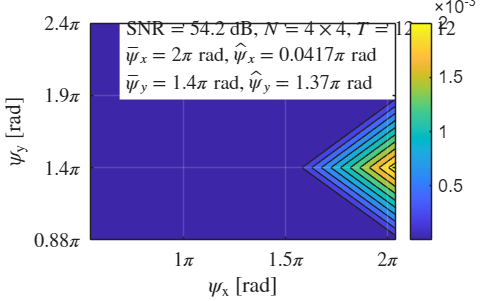

    %evaluating the meta-atom indexes
    n=1:N(i_N);
    n_y=ceil(n/N_x(i_N)); %see [1, Eq.(12)]
    n_x=n-(n_y-1)*N_x(i_N); %see [1, Eq.(13)]
    %Implementing Eq. (14)
    n_psi=n; %as follows from the description below [1, Eq.(16)]
    n_psi_y=ceil(n_psi/N_x(i_N)); %see [1, Eq.(12)]
    n_psi_x=n_psi-(n_y-1)*N_x(i_N); %see [1, Eq.(13)]
    % n_psi=n;
    % n_psi_x=n_x; %as follows from the description below [1, Eq.(16)]
    % n_psi_y=n_y; %as follows from the description below [1, Eq.(16)]
    % coefficients function in Equation (14)
    %index n_s refers to the space component of the DFT (per column),
    %index n_phy refers to the frequency component (per row)
    G_func = @(n,n_psi) exp(-1i*2*pi*(n_psi_x(n_psi)-1)/N_x(i_N).*(n_x(n)-1)).*exp(-1i*2*pi*(n_psi_y(n_psi)-1)/N_y(i_N).*(n_y(n)-1));
    [n_psi,n_s] = ndgrid(1:N(i_N), 1:N(i_N));
    G=G_func(n_s,n_psi);

#### Transmission coefficient matrix $\mathbf{\Upsilon_0}$ in Eq. (17)

**Description**: This matrix introduces a frequency-shift of parameter $t_\psi$ given by index `t_psi`. The parameter $t_\psi$ is calculated within the third dimension for the matrix $\mathbf{\Upsilon_0}$. The other two dimensions denote the Eq. (17) for a given $t_\psi$.

    r_psi_x_y_t=cell(T(end),length(T));%2DFT calculation in Eq. (24), the rows represent the abstract frequency n_psi, the columns represent the shifted frequency with t_psi

    for i_t=1:length(T)%looping over the number of snapshoots
        t_psi=1:T(i_t);%parameter t_psi in Eq.(17)
        Upsilon=zeros(N(i_N),N(i_N),T(i_t));%matrix Upsilon in Eq. (17)
        G_Upsilon=zeros(N(i_N),N(i_N),T(i_t));%2DFT kernel in Eq. (23)        
        max_r_psi_x_y_N=zeros(T(i_t),3);%this matrix stores per row the maximum and the position of the maximum in the received sequence
        %evaluating the snapshots indexes
        t=1:T(i_t);
        t_y=ceil(t/T_x(i_t)); %see [1, Eq.(12)]
        t_x=t-(t_y-1)*T_x(i_t); %see [1, Eq.(13)]
    
        % Implementing Eq. (18)
        % coefficients function in Equations (19) and (20)
        U_func = @(n,t_n) exp(1i*(-2*pi*(n_x(n)-1)*(t_x(t_n)-1)/(N_x(i_N)*T_x(i_t))-2*pi*(n_y(n)-1)*(t_y(t_n)-1)/(N_y(i_N)*T_y(i_t))));
       
    
        for i_itr=1:total_iteration%looping over the number of transmitted packets per snapshoot
        
            for pos=1:total_MUpositions%looping over the total of positions

                %Position
                %Fixed
                % MU_Pos = [SIM_Pos(1) SIM_Pos(2) 0];% MU on floor
                %Random
                MU_Pos = [SIM_Pos(1)+1/2*((L_hall+W_hall)*randn(1,1)+W_hall)...
                          SIM_Pos(2)+1/2*((L_hall+W_hall)*randn(1,1)+W_hall)...
                          0];        % MU on floor


#### Steering vector $\mathbf {a}\left ({{ \bar {\psi } _{\textrm {x}}, \bar {\psi } _{\textrm {y}} }}\right)\,\in\,\mathbb{C}^{N\times1}$ in Eq. (9)

                % psi_x(i_N,i_t,i_itr)=(theta_max-theta_min)*rand()+theta_min;%random generation of the x-component for the electric angle, the values for theta_min and theta_max are evaluated in the Parameters.mlx file
                % psi_y(i_N,i_t,i_itr)=(theta_max-theta_min)*rand()+theta_min;%random generation of the y-component for the electric angle, the values for theta_min and theta_max are evaluated in the Parameters.mlx file
                % psi_x(i_N,i_t,i_itr)=2*pi*rand();%random generation of the x-component for the electric angle
                % psi_y(i_N,i_t,i_itr)=2*pi*rand();%random generation of the x-component for the electric angle
                % psi_x(i_N,i_t,i_itr)=1*pi;%deterministic x-component for the electric angle
                % psi_y(i_N,i_t,i_itr)=pi/2;%deterministic x-component for the electric angle

                %Evaluating the MU elevation angle (theta) measured from +z downward
                %and azimuth (phi) angle around z, from +x toward +y
                v = SIM_Pos - MU_Pos;      % direction the SIM sees (arrival direction)
                v = v ./ norm(v);          % normalize
                % elevation (theta): angle *down from z*
                theta = acos(v(3));          % in radians  (θ ∈ [0, π])
                theta_deg = acosd(v(3));    % degrees
                % azimuth (phi)
                phi = atan2(v(2), v(1));       % in radians
                phi_deg = atan2d(v(2), v(1)); % degrees

                % Transforming physical angles theta and phi into the electric
                % angles psi_x and psi_Y
                psi_x = waveform_k*lambda/2 .* sin(theta) .* cos(phi);   % Eq. (1)
                psi_y = waveform_k*lambda/2 .* sin(theta) .* sin(phi);   % Eq. (2)

%fixing the electric angles
% psi_x=pi/8;
% psi_y=pi/8;

                % transforming the angles in the range [0 2π]
                if psi_x < 0
                    psi_x = psi_x + 2*pi;
                end
                if psi_y < 0
                    psi_y = psi_y + 2*pi;
                end

                %received signal
                a_psi_x=exp(1i*psi_x(i_N,i_t,i_itr)*((1:N_x(i_N))-1))';
                a_psi_y=exp(1i*psi_y(i_N,i_t,i_itr)*((1:N_y(i_N))-1))';
                a_psi_x_y=kron(a_psi_y,a_psi_x);

                %completing the matrix Upsilon, the loop goes in the third dimension with
                %the parameter t.
                for i_t_psi=1:T(i_t)
                    v_0=U_func(n,i_t_psi);

                    %Implementing Eq. (17)
                    Upsilon(:,:,i_t_psi)=diag(v_0');


#### Product $\mathbf{G}\mathbf{\Upsilon_0}$ in Eq. (23)

                    %implementing Eq. (23)
                    G_Upsilon(:,:,i_t_psi)=G*Upsilon(:,:,i_t_psi);


#### Evaluating the received signal as $\textbf {r}=\sqrt {\varrho }\textbf {G}\textbf {\Upsilon } _{0}\textbf {a}\left ({{ \psi _{\textrm {x}},\psi _{\textrm {y}} }}\right)s+\textbf {u}$ in Eq. (24)

                    s=1;%(randn(1,1)+1i*randn(1,1))/sqrt(2);
                    % u=(randn(N(i_N),1)+1i*randn(N(i_N),1))/sqrt(2);
                    % u=0;
                    % r_psi_x_y_t{i_t_psi,i_t}=sqrt(db2pow(SNR_dB))*G_Upsilon(:,:,i_t_psi)*a_psi_x_y*s+u;


#### CDL channel

                    % communication distance between MU and SIM (meters)
                    d_comm = norm(MU_Pos - SIM_Pos);
                    %Pathloss model for indoor factory according to Table 7.4.1-1 pp. 29 in [1]
                    PL_dB=31.84+21.5*log10(d_comm)+19*log10(fc/1e9);
                    %free-space formula
                    % PL_dB=20*log10(4*pi*d_comm*fc/physconst('LightSpeed'));
                    % link budget
                    %Received power
                    Prx_dB=(Ptx_dBm + Gtx_dBi + Grx_dBi - PL_dB);
                    scale = sqrt( (10^(Prx_dB/10)) / 1000 );
                    %CDL received signal
                    [rxWaveform, pathGains] = cdl(s*ones(1,txArray.NumElements));
                    %Denormalized signal
                    rxWaveform = rxWaveform * scale;
                    r_psi_x_y_t{i_t_psi,i_t}=G_Upsilon(:,:,i_t_psi)*a_psi_x_y.*rxWaveform'+wgn(N_x*N_y,1,var_noise_dB);                   


#### Finding the 2D-DFT maximum and indexes $n_{\psi_x}$ and $n_{\psi_y}$ for the received sequence per parameter-value $t_\psi$ in the 2D plane

**Description**: The maximum for Eq. (24) is found with the absolute value of $\mathbf{r}$ for the given parameter $t_\psi$. The maximum is found in the 2D plane, where the index $n_\psi$ and $t_\psi$ are represented with the corresponding $x$ and $y$ dimensions, as follows Equation (15)-(16) and (21)-(22), respectively. The vector $\mathbf{r}$ is transformed to the 2D domain with the operations in the code below: reshape, transpose, flipud, and fliplr. These functions are for representing the 2D plane with the two axes and in a convenient direction to plot later. Within the code, the matrix `max_r_psi_x_y_t` stores per row the maximum of the 2D DFT operation in the first position, the other two positions follows the indexes in x and y of the maximum. Each row of `max_r_psi_x_y_t` represents a parameter $t_\psi$.

                    [max_r_psi_x_y_N(i_t_psi,1),I]=max(flipud(fliplr(reshape(abs(r_psi_x_y_t{i_t_psi,i_t}), [N_x(i_N), N_y(i_N)])))',[],'all');

                    max_r_psi_x_y_N(i_t_psi,2)=ceil(I/N_x(i_N));
                    max_r_psi_x_y_N(i_t_psi,3)=I-(max_r_psi_x_y_N(i_t_psi,2)-1)*N_x(i_N);

                end

                %evaluating the SNR
                SNR_dB(pos)=Prx_dB-var_noise_dB

#### Finding $t_{\psi_x}$ and $t_{\psi_y}$ for the 2D-DFT peak

                [~,max_t_psi(i_N,i_t,i_itr)]=max(max_r_psi_x_y_N(:,1),[],'all');
                max_t_psi_x(i_N,i_t,i_itr)=t_x(max_t_psi(i_N,i_t,i_itr));
                max_t_psi_y(i_N,i_t,i_itr)=t_y(floor(max_t_psi(i_N,i_t,i_itr)/T_x(i_t))*T_x(i_t)+mod(max_t_psi(i_N,i_t,i_itr),T_x(i_t)));

#### Finding the  xy-coordinates of $n_\psi$ for the 2D-DFT peak

                max_n_psi_x(i_N,i_t,i_itr)=max_r_psi_x_y_N(max_t_psi(i_N,i_t,i_itr),2);
                max_n_psi_y(i_N,i_t,i_itr)=max_r_psi_x_y_N(max_t_psi(i_N,i_t,i_itr),3);

#### Finding the bins of the electric angles $k_{\psi_x}$ and $k_{\psi_y}$

                % k_x_est(i_N,i_t,i_itr)=max_n_psi_x(i_N,i_t,i_itr)+(max_t_psi_x(i_N,i_t,i_itr))/T_x;
                % k_y_est(i_N,i_t,i_itr)=max_n_psi_y(i_N,i_t,i_itr)+(max_t_psi_y(i_N,i_t,i_itr))/T_y;

#### Finding the  estimated electric angles $\psi_x$ and $\psi_y$

                % psi_x_est(i_N,i_t,i_itr)=2*pi*(k_x_est(i_N,i_t,i_itr))/N_x(i_N);
                % psi_y_est(i_N,i_t,i_itr)=2*pi*(k_y_est(i_N,i_t,i_itr))/N_y(i_N);
                psi_x_est(i_N,i_t,i_itr)=mod(2*pi*(max_n_psi_x(i_N,i_t,i_itr)+(max_t_psi_x(i_itr))/T_x(i_t))/N_x(i_N),2*pi);
                psi_y_est(i_N,i_t,i_itr)=mod(2*pi*(max_n_psi_y(i_N,i_t,i_itr)+(max_t_psi_y(i_itr))/T_y(i_t))/N_y(i_N),2*pi);

#### Evaluating the relative errors

                psi_x_relative_errors(i_N,i_t,i_itr)=abs(psi_x(i_N,i_t,i_itr)-psi_x_est(i_N,i_t,i_itr))/abs(psi_x(i_N,i_t,i_itr))*100;
                psi_y_relative_errors(i_N,i_t,i_itr)=abs(psi_y(i_N,i_t,i_itr)-psi_y_est(i_N,i_t,i_itr))/abs(psi_y(i_N,i_t,i_itr))*100;

#### Testing a particular condition

                % if(psi_x_relative_errors(i_N,i_t,i_itr)>100)
                figure
                R_psi_x_y = flipud(fliplr(reshape(abs(r_psi_x_y_t{max_t_psi,i_t}), [N_x(i_N), N_y(i_N)])))';
                %coordinates with the electric angle indexes k_x and k_y as defined in
                %the Parameters.mlx file
                % [X,Y] = meshgrid(linspace(1,N_x(i_N),N_x(i_N))+(max_t_psi_x(i_N,i_t,i_itr)-1)/T_x,linspace(1,N_y(i_N),N_y(i_N))+(max_t_psi_y(i_N,i_t,i_itr)-1)/T_y);
                % %coordinates with the electric angle
                [X,Y] = meshgrid(2*pi/N_x(i_N)*(linspace(1,N_x(i_N),N_x(i_N))+(max_t_psi_x(i_N,i_t,i_itr))/T_x),...
                    2*pi/N_y(i_N)*(linspace(1,N_y(i_N),N_y(i_N))+(max_t_psi_y(i_N,i_t,i_itr))/T_y));

                contourf(X,Y,abs(R_psi_x_y));
                % contourf(abs(R_psi_x_y));
                colorbar
                grid on;
                xlabel('$\psi_\mathrm{x}$ [rad]','Interpreter','latex');
                ylabel('$\psi_\mathrm{y}$ [rad]','Interpreter','latex');
                %Tick angles
                X=2*pi/N_x(i_N)*(linspace(1,N_x(i_N),N_x(i_N))+(max_t_psi_x(i_N,i_t,i_itr)-1)/T_x);
                set(gca, 'XTick', X);
                X_Tick_text=cell(1,length(X));
                for j=1:length(X)
                    X_Tick_text{j}=strcat('$',num2str((X(j))/pi,2),'\pi$');
                end
                set(gca, 'XTickLabel', [X_Tick_text], 'TickLabelInterpreter', 'latex');

                Y=2*pi/N_y(i_N)*(linspace(1,N_y(i_N),N_y(i_N))+(max_t_psi_y(i_N,i_t,i_itr))/T_y);
                set(gca, 'YTick', Y);
                Y_Tick_text=cell(1,length(Y));
                for j=1:length(Y)
                    Y_Tick_text{j}=strcat('$',num2str((Y(j))/pi,2),'\pi$');
                end
                set(gca, 'YTickLabel', [Y_Tick_text], 'TickLabelInterpreter', 'latex');
                %
                % set(gca, 'YTick', [0:0.25:2]*pi);
                % set(gca, 'YTickLabel', [{"0","$0.25\pi$","$0.5\pi$","$0.75\pi$","\pi","$1.25\pi$","1.5\pi","$1.75\pi$","2\pi"}], 'TickLabelInterpreter', 'latex');
                % axis([0 2*pi 0 2*pi])
                set(gca,'FontSize',font+5,'GridColor','white');
                legend_text={strcat('SNR$=',num2str(SNR_dB,3),'$ dB,',' $N=$',num2str(N_x(i_N)),'$\times$',num2str(N_y(i_N)),', $T=$',num2str(T_x),'$\times$',num2str(T_y)),...
                    strcat('$\bar{\psi}_x=',num2str(psi_x(i_N,i_t,i_itr)/pi,2),'\pi$ rad, ',' $\hat{\psi}_x=',num2str(psi_x_est(i_N,i_t,i_itr)/pi,3),'\pi$ rad')...
                    strcat('$\bar{\psi}_y=',num2str(psi_y(i_N,i_t,i_itr)/pi,2),'\pi$ rad, ',' $\hat{\psi}_y=',num2str(psi_y_est(i_N,i_t,i_itr)/pi,3),'\pi$ rad')};
                % Get current axis limits
                x_limits = xlim;
                y_limits = ylim;
                % Define position (upper-right corner)
                x_pos = x_limits(2) - 0.89 * diff(x_limits); % Slightly inside the right edge
                y_pos = y_limits(1) + 0.85 * diff(y_limits); % Slightly inside the top edge
                text(x_pos,y_pos,legend_text,'Interpreter','latex','BackgroundColor','w','FontSize',font);
                set(gca,'FontSize',font);
                % end




                % disp(['Relative Errors for Psi_x is ',num2str(psi_x_relative_errors(i_SNR),2),'%'])
                % disp(['Relative Errors for Psi_y is ',num2str(psi_y_relative_errors(i_SNR),2),'%'])
            end
            % save in simulation_results.mat the relative error in x and y,
            % the variables related to the estimation of the electric angles,
            % and the varibles to plot the 2D-DFT
            % plot_stream=strcat('./results/plot_N_',num2str(i_N));
            % save(plot_stream,"r_psi_x_y_t","max_t_psi","max_t_psi_x","max_t_psi_y","i_N","psi_x","psi_y","psi_x_est","psi_y_est","N","T");
        end
    end
end

toc;
% save in simulation_results.mat the relative error in x and y and 
% the variables related to the estimation of the electric angles
% save ./results/simulation_results psi_x_relative_errors psi_y_relative_errors ...
%      psi_x_est psi_y_est N T;


### References

[1] J. An et al., "Stacked Intelligent Metasurface Performs a 2D DFT in the Wave Domain for DOA Estimation," in ICC 2024 - IEEE International Conference on Communications, June 2024, pp. 3445–3451. doi: 10.1109/ICC51166.2024.10622963.